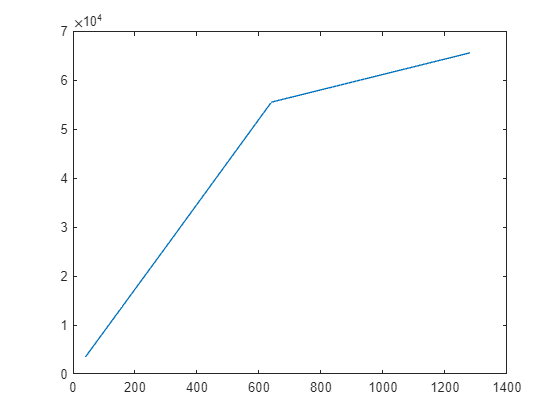

t_int = [40, 80, 160, 320, 640, 1280];
R_integration_time = reshape(cell2mat(RED(10,:)),[],6);
R_integration = R_integration_time./R_integration_time(:,6); % dividing
R_dev_n = R_stddev./R_integration_time(:,6);
% each channel by the maximum value before saturation
% std(R_integration)
plot(t_int, R_integration_time(7, :))

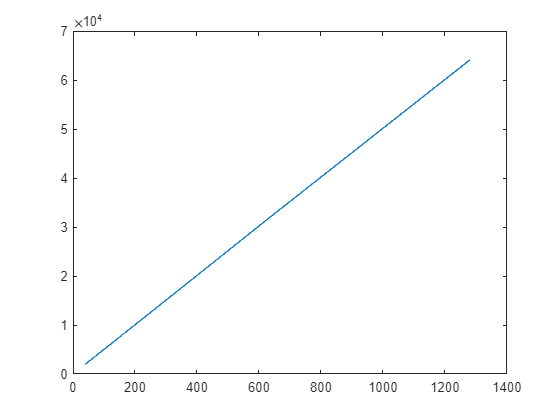

% hold on
for i = 2:9
    plot(t_int, R_integration_time(i, :))
end

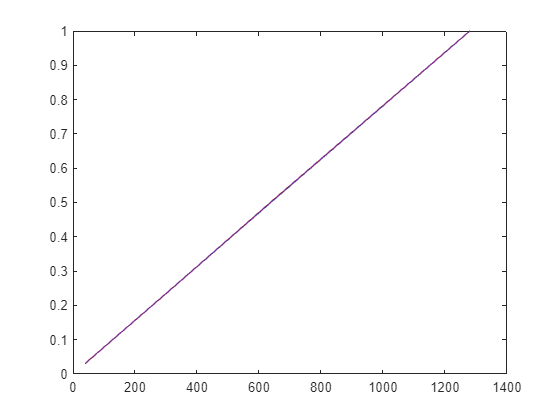

% hold off

plot(t_int, R_integration(11, :))
hold on
for i = 12:14
    plot(t_int, R_integration(i, :))
end
hold off


R_stddev = reshape(cell2mat(R_dev(10,:)),[],6)

R_stddev =          0         0         0         0    0.7592    0.3078
         0         0         0    0.4104    0.4104    0.4443
    0.2236         0         0         0    0.8208    0.5130
         0         0         0         0    0.9787    0.6070
         0         0         0    0.2236    0.4104    0.2236
    1.0809    1.1239    1.1642    3.2703   32.7984   19.3561
    0.7592    1.0894    1.2085    3.0157   16.1460         0
         0         0         0         0    0.7592    0.6407
    0.8127    1.0699    0.8256    2.2124   18.3550    9.9540
         0         0    0.3078    0.5026    3.3779    2.3864


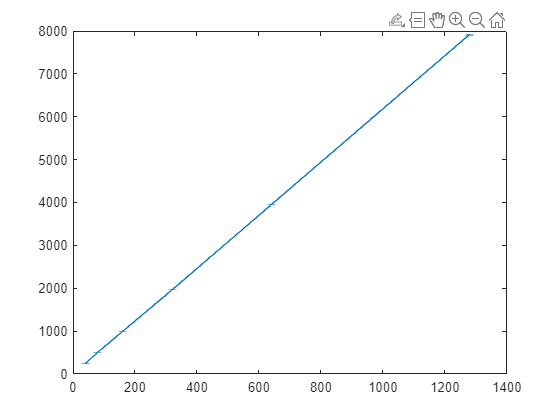

errorbar(t_int, R_integration_time(10,:),R_stddev(10,:))

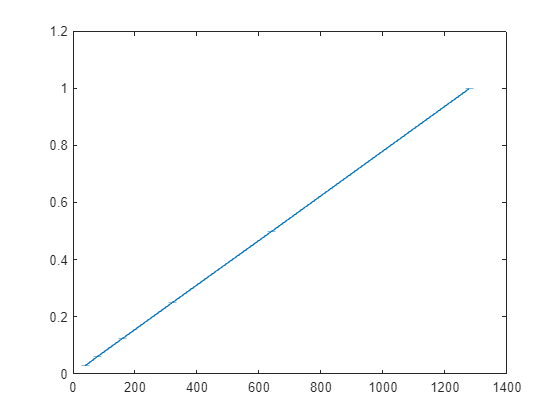


errorbar(t_int, R_integration(10,:),R_dev_n(10,:))

% R_integration_time = reshape(cell2mat(RED(1,:)),[],6);
% R_integration = R_integration_time./R_integration_time(:,6);
% 
% plot(t_int, R_integration(1, :))
% hold on
% for i = 2:9
%     plot(t_int, R_integration(i, :))
% end
% hold off
% 
% plot(t_int, R_integration(11, :))
% hold on
% for i = 12:14
%     plot(t_int, R_integration(i, :))
% end
% hold off